%exp_1
m = 1000;
b = 50;
u = 500;
num = [1];
den = [m b];
cruise = tf(num, den)

cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.
Model Properties


step(cruise);

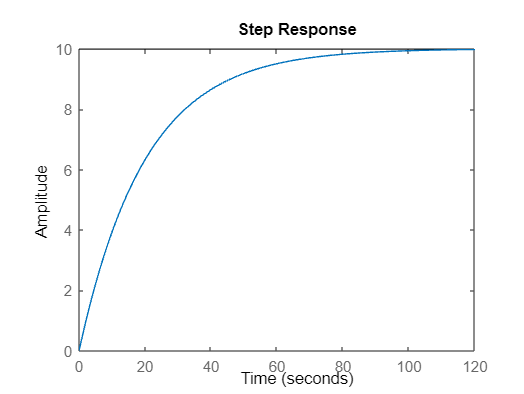

step(u*cruise);

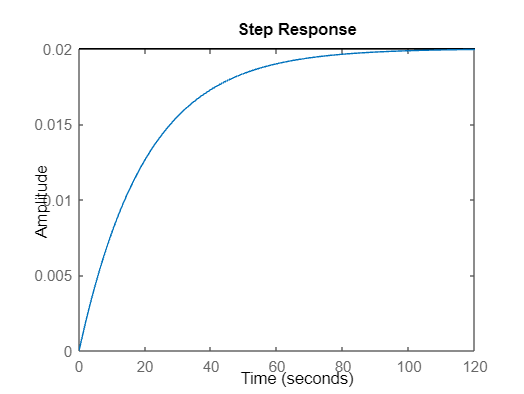

A = [-b/m];
B = [1/m];
C = [1];
D = 0;
Cruise = ss(A, B, C, D);
step(Cruise);

J = 0.01;
b = 0.1;
K = 0.01;
L = 0.5;
R = 1;
num = [K];
den = [(J*L)  (J*R + L*b)  R*b + K^2];
cruise = tf(num, den)

cruise =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


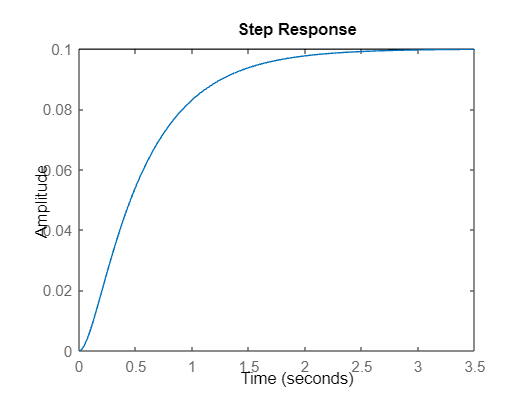

step(cruise)

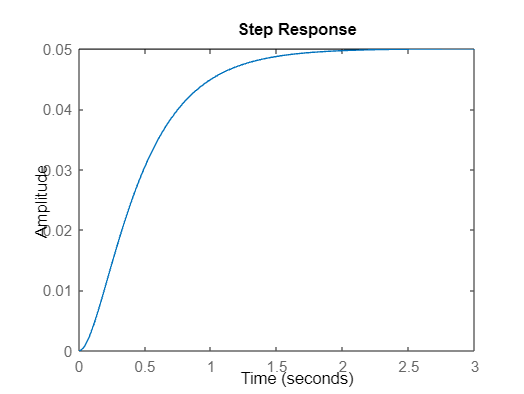

%exp_2
M = 1;
b = 10;
k = 20;
num = 1;
den = [M b k];
plant = tf(num, den);
step(plant);

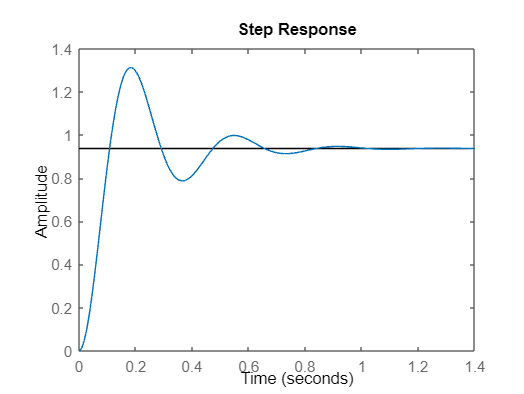


Kp = 300;
contr = Kp;
sys_cl = feedback(contr*plant,1);
step(sys_cl)

M = 1;
b = 10;
k = 20;
num = 1;
den = [M b k];
plant = tf(num, den);
step(plant);

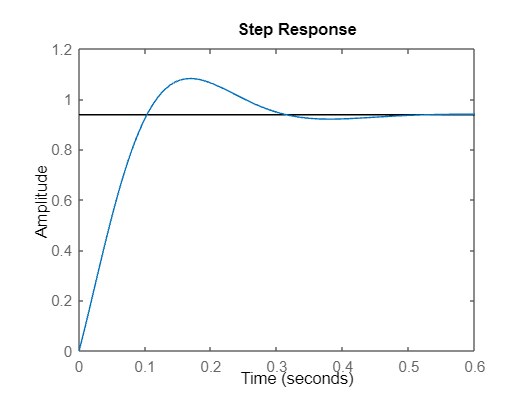


Kp = 300;
Kd = 10;
contr = tf([Kd Kp],1);
sys_cl = feedback(contr*plant,1);
step(sys_cl)

M = 1;
b = 10;
k = 20;
num = 1;
den = [M b k];
plant = tf(num, den);
step(plant);

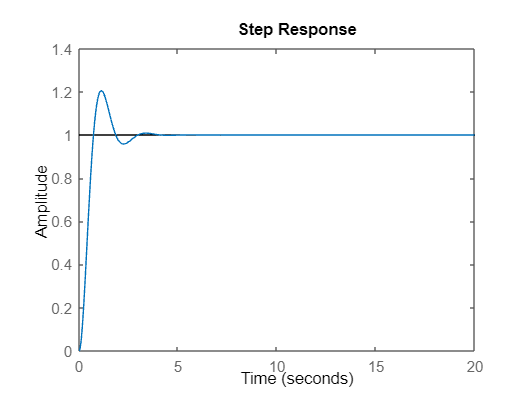


Kp = 30;
Ki = 70;
contr = tf([Kd Ki],[1 0]);
sys_cl = feedback(contr*plant,1);
t = 0:0.01:20;
step(sys_cl,t)

M = 1;
b = 10;
k = 20;
num = 1;
den = [M b k];
plant = tf(num, den);
step(plant);


Kp = 350;
Ki = 300

Ki = 300

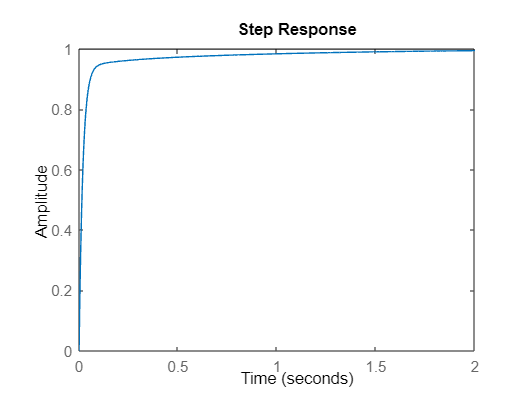

Kd = 50;
contr = tf([Kd Kp Ki],[1 0]);
sys_cl = feedback(contr*plant,1);
step(sys_cl)